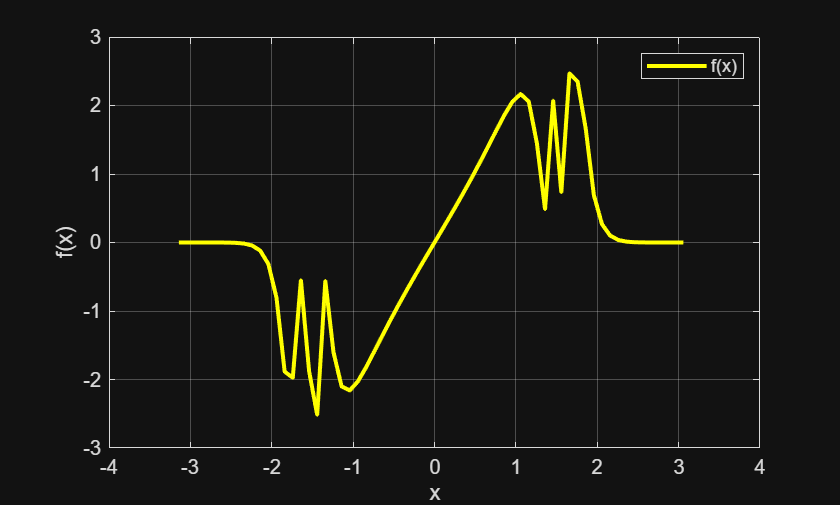

clc;
clear;
close all;

x = -pi:0.1:pi;

y = tan(sin(x)) + sin(tan(x));

figure;
plot(x, y, 'y', 'LineWidth', 2);
grid on;
xlabel('x');
ylabel('f(x)');
legend('f(x)');

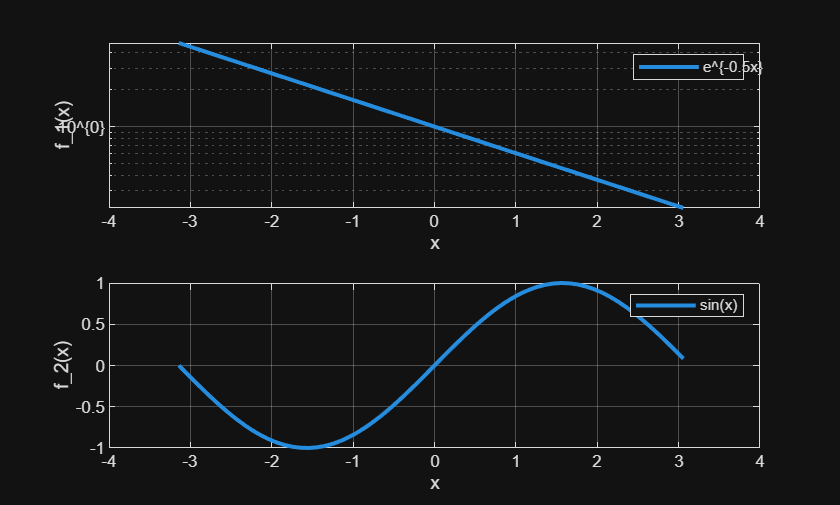


y1 = exp(-0.5*x);
y2 = sin(x);

figure;

subplot(2,1,1);
semilogy(x, y1, 'LineWidth', 2);
grid on;
xlabel('x');
ylabel('f_1(x)');
legend('e^{-0.5x}');

subplot(2,1,2);
plot(x, y2, 'LineWidth', 2);
grid on;
xlabel('x');
ylabel('f_2(x)');
legend('sin(x)');

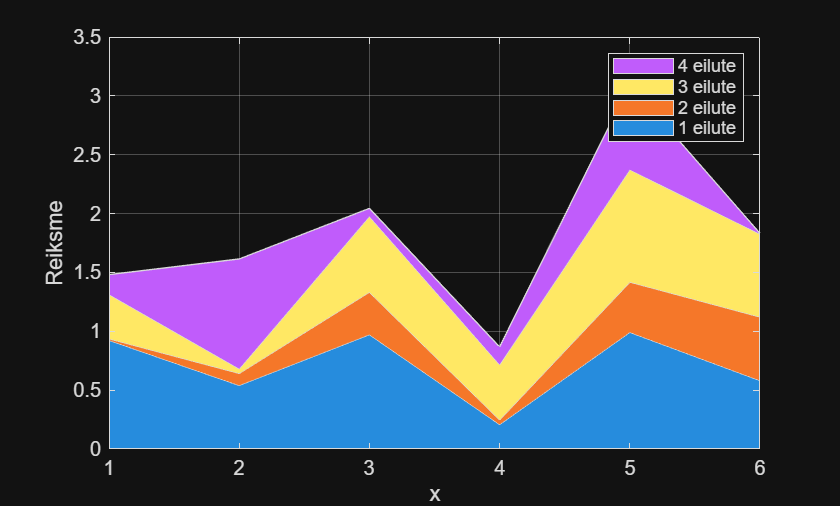


N = 4;
M = 6;

A = rand(N, M);

figure;
area(A');
grid on;
xlabel('x');
ylabel('Reiksme');
legend('1 eilute', '2 eilute', '3 eilute', '4 eilute');

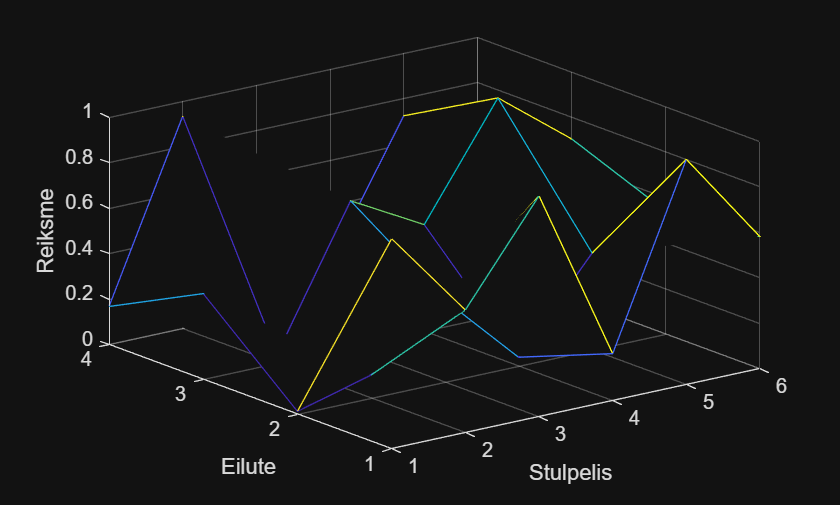


figure;
mesh(A);
grid on;
xlabel('Stulpelis');
ylabel('Eilute');
zlabel('Reiksme');

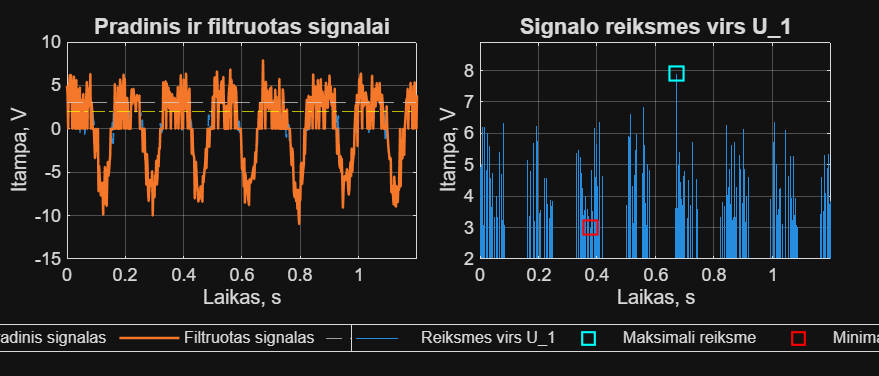

clc;
clear;
close all;

A = 5;
f = 6;
sigma = 1.5;
U1 = 3;
U2 = 2;

t = 0:0.002:1.2;

s = A*sin(2*pi*f*t) + 0.5*A*cos(4*pi*f*t);
n = sigma * randn(size(t));
signalas = s + n;

filtruotas_signalas = signalas;
filtruotas_signalas(abs(filtruotas_signalas) < U2) = 0;

figure('Position', [100 100 1400 600]);

tiledlayout(1,2, 'TileSpacing','compact', 'Padding','compact');

nexttile

plot(t, signalas, '--', 'LineWidth', 1)
hold on

plot(t, filtruotas_signalas, '-', 'LineWidth', 1.25)

yline(U1, '--')
yline(U2, '-.', 'Color', 'y')

grid on
xlabel('Laikas, s')
ylabel('Itampa, V')

title('Pradinis ir filtruotas signalai', ...
    'FontWeight','bold', ...
    'FontSize',11)

legend('Pradinis signalas', ...
       'Filtruotas signalas', ...
       'U_1 = 3', ...
       'U_2 = 2', ...
       'Location','southoutside', ...
       'Orientation','horizontal')

xlim([0 1.2])


nexttile

idx = signalas > U1;

t_atrinktas = t(idx);
signalas_atrinktas = signalas(idx);

stem(t_atrinktas, signalas_atrinktas, ...
    'Marker','none')

hold on

[max_reiksme, max_idx] = max(signalas_atrinktas);
[min_reiksme, min_idx] = min(signalas_atrinktas);

plot(t_atrinktas(max_idx), max_reiksme, ...
    'cs', ...
    'MarkerSize',9, ...
    'LineWidth',1.5)

plot(t_atrinktas(min_idx), min_reiksme, ...
    'rs', ...
    'MarkerSize',9, ...
    'LineWidth',1.5)

grid on
xlabel('Laikas, s')
ylabel('Itampa, V')

title('Signalo reiksmes virs U_1', ...
    'FontWeight','bold', ...
    'FontSize',11)

legend('Reiksmes virs U_1', ...
       'Maksimali reiksme', ...
       'Minimali reiksme', ...
       'Location','southoutside', ...
       'Orientation','horizontal')

xlim([0 1.2])
ylim([2 max_reiksme+1])